# **CA#1 **

## **Name: Sogol Goodarzi **

## **SID: 810198467**

# **Part 6**

### Solution 1 : with "filtic", "residuez" and "conv" functions

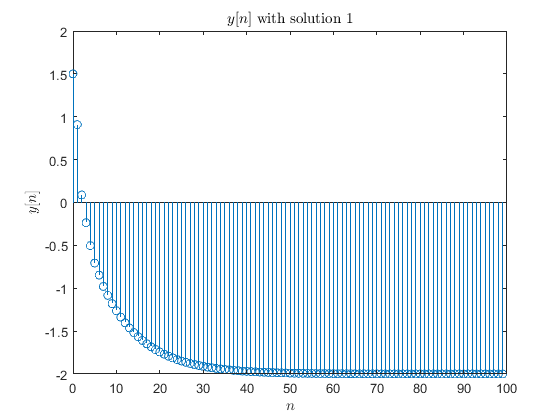

warning('off');
b=[0.45,0.4,-1];
a=[1,-0.4,-0.45];
bX=[6,-4];         %% Nominator of X(Z)
aX=[2,-3,1];       %% Denominator of X(Z)
yi=[0,3];          %% Initial values of y
xi=[2,2];          %% Initial values of x
IC=filtic(b,a,yi,xi);     %% Initial condition
bY=conv(b,bX)+conv(IC,aX);
aY=conv(a,aX);
[r,p,k]=residuez(bY,aY);
amp_p=abs(p);      %% p amplitude
ang_p=angle(p);    %% p angle
n=0:1:99;
y=r.*amp_p.^n.*exp(-1i*pi*n.*ang_p);
y=sum(y);
stem(n,y);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y[n]$','Interpreter','latex')
title ('$y[n]$ with solution 1','Interpreter','latex')

amp_p

amp_p =     1.0000
    0.9000
    0.5000
    0.5000


ang_p

ang_p =          0
         0
         0
    3.1416


r

r =    -2.0000
    2.1116
    1.7188
   -0.3304


### Solution 2 : with "filtic" and "filter" functions

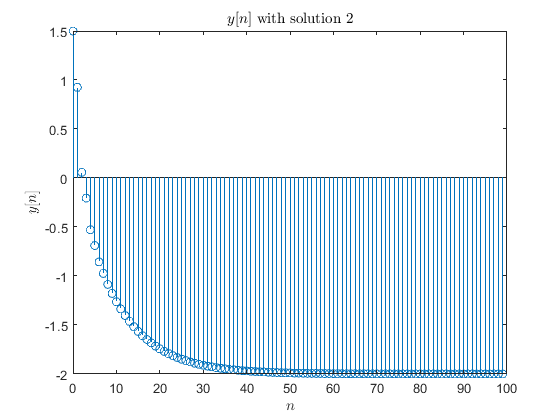

n=0:1:99;
x=(1/2).^n+2;
b=[0.45,0.4,-1];
a=[1,-0.4,-0.45];
yi=[0,3];
xi=[2,2];
IC=filtic(b,a,yi,xi);
y=filter(b,a,x,IC);
stem(n,y);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y[n]$','Interpreter','latex')
title ('$y[n]$ with solution 2','Interpreter','latex')

### Zero-state Response (particular response) 

### 
$$y_p \left\lbrack n\right\rbrack$$


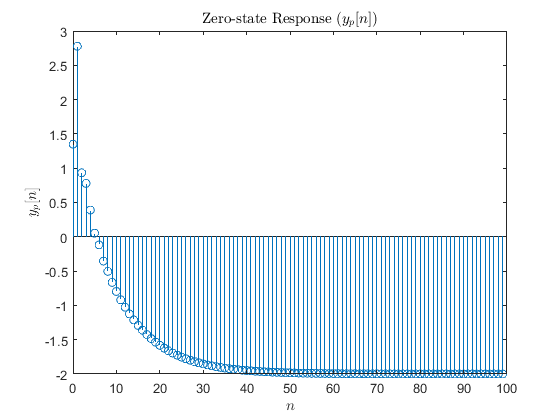

b=[0.45,0.4,-1];
a=[1,-0.4,-0.45];
bX=[6,-4];   
aX=[2,-3,1]; 
bYp=conv(b,bX);
aYp=conv(a,aX);
[r,p,k]=residuez(bYp,aYp);
amp_p=abs(p); 
ang_p=angle(p); 
n=0:1:99;
yp=r.*amp_p.^n.*exp(-1i*pi*n.*ang_p);
yp=sum(yp);
stem(n,yp);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y_p[n]$','Interpreter','latex')
title ('Zero-state Response ($y_p[n]$)','Interpreter','latex')

### Zero-input Response (homogeneous response)

### 
$$y_h \left\lbrack n\right\rbrack$$


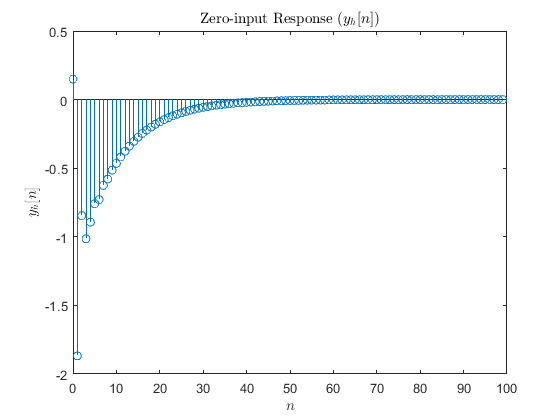

yi=[0,3];
xi=[2,2];
bYh=filtic(b,a,yi,xi);
aYh=a;
[r,p,k]=residuez(bYh,aYh);
amp_p=abs(p);  
ang_p=angle(p);  
n=0:1:99;
yh=r.*amp_p.^n.*exp(-1i*pi*n.*ang_p);
yh=sum(yh);
stem(n,yh);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y_h[n]$','Interpreter','latex')
title ('Zero-input Response ($y_h[n]$)','Interpreter','latex')

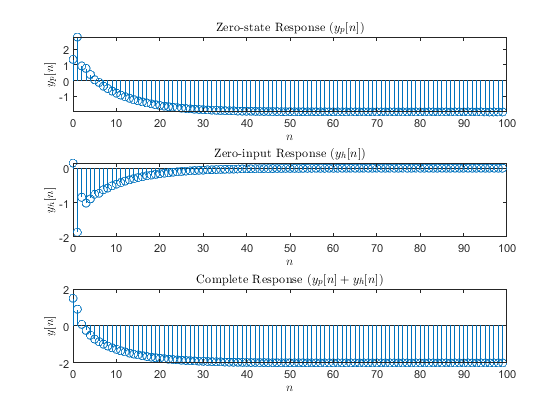

subplot(3,1,1);
stem(n,yp);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y_p[n]$','Interpreter','latex')
title ('Zero-state Response ($y_p[n]$)','Interpreter','latex')
subplot(3,1,2);
stem(n,yh);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y_h[n]$','Interpreter','latex')
title ('Zero-input Response ($y_h[n]$)','Interpreter','latex')
subplot(3,1,3);
y=yp+yh;
stem(n,y);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y[n]$','Interpreter','latex')
title ('Complete Response ($y_p[n]+y_h[n]$)','Interpreter','latex')

r = [-2 , 2.1116 , 1.7188 , -0.3304]

ang_p = [0 , 0 , 0 , 3.1416]

amp_p = [1 , 0.9 , 0.5 , 0.5]

### Sready_state Response 

### 
$$y_{\mathrm{ss}} \left\lbrack n\right\rbrack =-2\times 1^n$$


y_ss=-2*1.^n;

### Transient Response 

### 
$$y_t \left\lbrack n\right\rbrack =2\ldotp 1116{\left(0\ldotp 9\right)}^n +1\ldotp 7188{\left(0\ldotp 5\right)}^n -0\ldotp 3304{\left(0\ldotp 5\right)}^n$$


y_t=2.1116*0.9.^n+1.7188*0.5.^n-0.3304*0.5.^n;

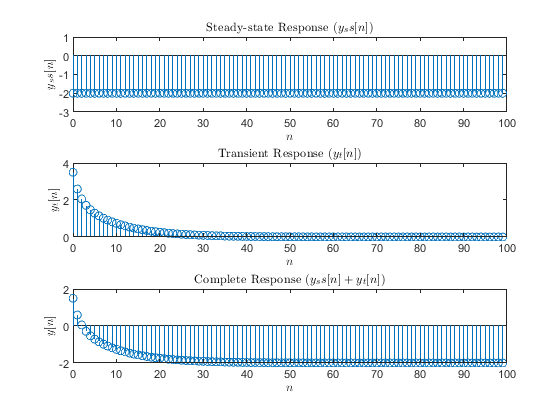

subplot(3,1,1);
stem(n,y_ss);
ylim([-3 1]);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y_ss[n]$','Interpreter','latex')
title ('Steady-state Response  ($y_ss[n]$)','Interpreter','latex')
subplot(3,1,2);
stem(n,y_t);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y_t[n]$','Interpreter','latex')
title ('Transient Response  ($y_t[n]$)','Interpreter','latex')
subplot(3,1,3);
y=y_ss+y_t;
stem(n,y);
xlabel ('$n$','Interpreter','latex')
ylabel ('$y[n]$','Interpreter','latex')
title ('Complete Response ($y_ss[n]+y_t[n]$)','Interpreter','latex')